%%plotting depth cross-sections.
clc ; clear ; close all

%depth cross-section along a great circle path.
%specify starting/ending points (lat1,lon1,lat2,lon2) and # of points in between
lat1 = 47.5; lon1 = -120;
lat2 = 51.5; lon2 = -108;
latlon=  (lat1,lon1,lat2,lon2);%nearly North-south profile

%specify depth vectory
zii=[40:5:450];


%the profiles are stored in ps, px, pg and paz which have the dimension as
%length(latlon) by length(zii0). 
%no need to change lines blow.
%%
if exist('Fs','var')
else
    load F.interpolant.NA.mat
end


latlon(:,2)=mod(latlon(:,2),360);
dis0=distance(latlon(1,1),latlon(1,2),latlon(:,1),latlon(:,2));
dist = deg2km(dis0);


nz=length(zii);
nx=length(latlon);

%for nx*nz by 3 vector for interpolation
latloni=zeros(nx*nz,3);
for i=1:nz
    latloni((i-1)*nx+1:i*nx,:)=[latlon ones(nx,1)*zii(i)];
end
%
clf;colormap(flipud(jet(16)));
%az

%these lines illustrate how to get the values along the profile. The
%interpolation takes some time.
paz=Faz(latloni(:,1),latloni(:,2),latloni(:,3));
paz=reshape(paz,nx,nz);
px=Fx(latloni(:,1),latloni(:,2),latloni(:,3));
px=reshape(px,nx,nz);
pg=Fg(latloni(:,1),latloni(:,2),latloni(:,3));
pg=reshape(pg,nx,nz);
ps=Fs(latloni(:,1),latloni(:,2),latloni(:,3));
ps=reshape(ps,nx,nz);


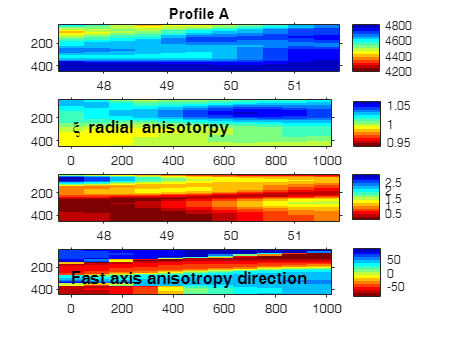


%plotting. Note the example profile goes nearly north-south so latitude is
%used as the x axis. You can use dis0 here too.
%
figure(1)

subplot(4,1,4);%anisotropy direction
imagesc(dist,zii,paz'); 
% set(gca,'xdir','reverse');
colorbar('vert');ylim([40 450]);
xtick0=get(gca,'xtick');
ht(4)=text(xtick0(1),300,'Fast axis anisotropy direction'); %note this line may not work for all cases.
%xi
subplot(4,1,2);%radial anisotorpy
imagesc(dist,zii,px'); 
caxis([.94 1.06])
% set(gca,'xdir','reverse');
colorbar('vert');ylim([40 450]);
ht(2)=text(xtick0(1),300,'\xi radial anisotorpy'); %note this line may not work for all cases.

%xi
subplot(4,1,3);%azimuthal anisotropy strength
imagesc(latlon(:,1),zii,pg');
% set(gca,'xdir','reverse');
colorbar('vert');ylim([40 450]);
ht(3)=text(xtick0(1),300,'dlnG azimuthal anisotropy strength'); %note this line may not work for all cases.

%dlnvs
subplot(4,1,1);%vs
imagesc(latlon(:,1),zii,ps');caxis([4200 4800]);
% set(gca,'xdir','reverse');
colorbar('vert');ylim([40 450]);
set(findobj(gcf,'type','axes'),'tickdir','out');
ht(1)=text(xtick0(1),300,'Vs'); %note this line may not work for all cases.

set(ht,'color','k','fontweight','bold');%again this may not work
title('Profile A');

## radial anisotorpy

fig = figure()

fig =   Figure (17) with properties:

      Number: 17
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


% img = imagesc(dist,zii,px'); hold on
[M,c] = contour(dist,zii,px');
ax = gca;
caxis([.94 1.06])
colorbar('vert');
ax.YLim = [0,300];
ax.XLim = [180,540];
ax.YDir = 'reverse'

ax =   Axes with properties:

             XLim: [180 540]
             YLim: [0 300]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1164 0.1100 0.6938 0.8150]
            Units: 'normalized'

  Show all properties


c.ShowText = 'on'

c =   Contour with properties:

    LineColor: 'flat'
    LineStyle: '-'
    LineWidth: 0.5000
         Fill: off
    LevelList: [0.9900 1 1.0100 1.0200 1.0300 1.0400 1.0500]
        XData: [11×1 double]
        YData: [40 45 50 55 60 65 70 75 80 85 90 95 100 105 110 115 120 125 130 135 140 145 150 155 160 165 170 175 180 185 190 195 200 205 210 215 220 225 230 235 240 245 250 255 260 265 270 275 280 285 290 295 300 305 310 315 320 325 330 335 340 … ]
        ZData: [83×11 double]

  Show all properties


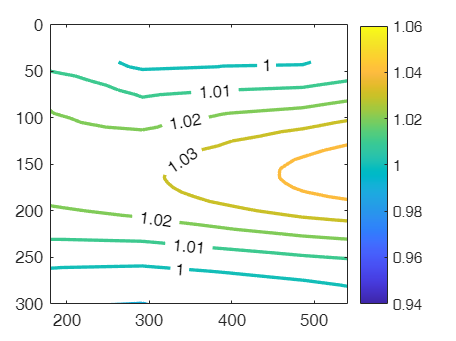

c.LineWidth = 2;

% ax.ylim([40 450]);
% ht(2)=text(xtick0(1),300,'\xi radial anisotorpy'); %note this line may not work for all cases.




















